% This MATLAB script processes raw seizure data to identify and mark critical
% transition points associated with seizures, specifically the seizure onset 
% (the point where a seizure begins) and the seizure offset (the point where 
% the seizure ends). 
%
% The code assumes that the input data consists of continuous time-series 
% recordings, such as EEG or neural activity, where seizure events manifest 
% as distinct patterns distinguishable from baseline activity. 
%
% Main functionalities may include:
% - Preprocessing: Filtering and cleaning the raw data to reduce noise 
%   and enhance features that distinguish seizure events.
% - Feature Extraction: Calculating metrics or detecting signal patterns 
%   indicative of seizure activity (e.g., amplitude thresholds, frequency bands).
% - Transition Point Detection:
%     - Seizure Onset: Identifying the time point at which the signal transitions 
%       from non-seizure (baseline) activity to seizure activity based on defined 
%       criteria.
%     - Seizure Offset: Identifying the time point at which the signal returns 
%       to baseline activity, marking the end of the seizure.
% - Output Markers: Storing or visualizing the identified onset and offset points 
%   for further analysis or validation.
%
% The resulting information can be used for:
% - Quantifying seizure durations and frequencies.
% - Training predictive models for seizure forecasting.
% - Informing therapeutic interventions like closed-loop neuromodulation.
%
% The code is designed for flexibility and may require user-defined parameters 
% such as thresholds, filters, or detection algorithms tailored to the specific 
% dataset and application.
%
% Note: Ensure that the input raw data is in the correct format, and verify that 
% any preprocessing steps (e.g., detrending, artifact removal) have been applied 
% as needed prior to running this script.
%
% Dependencies:
% - Signal Processing Toolbox (optional, for advanced filtering and feature extraction).
% - Statistical or Machine Learning Toolbox (if predictive modeling is integrated).

clear; clc; close all;
load('D:\No-Stim_Data\No-Stim_ES028_Cohort_08\Baseline_Data\Actual-data_Folders\r1_20240221_ES025_ES026_ES027_ES028\02-21-2024_18-18-30\Data_20240221_d_1.mat');

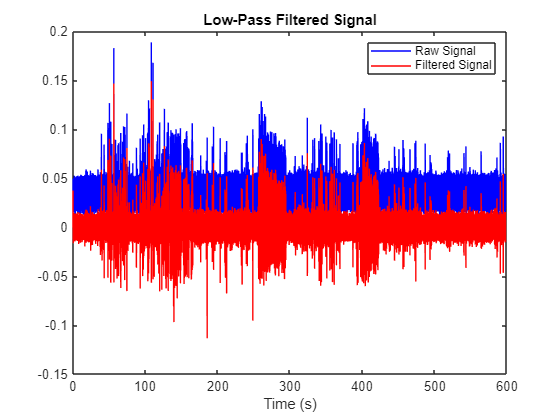

raw_eeg = data(:,1);
fs = fs_rec; % Sampling rate (Hz)
fc = [1 3000];  % Cutoff frequency (Hz)
signal_length = size(raw_eeg, 1);

[b, a] = butter(4, fc/(fs/2), 'bandpass'); % 4th-order Butterworth filter
filtered_signal = filtfilt(b, a, raw_eeg);
t_seconds = (0:signal_length-1)/fs;

% seconds = 5;
% t = 0:1/fs:seconds-1/fs; % 5 seconds of data


% Plot the result
figure;
plot(t_seconds, raw_eeg, 'b'); hold on;
plot(t_seconds, filtered_signal, 'r');
xlabel('Time (s)');
legend('Raw Signal', 'Filtered Signal');
title('Low-Pass Filtered Signal');

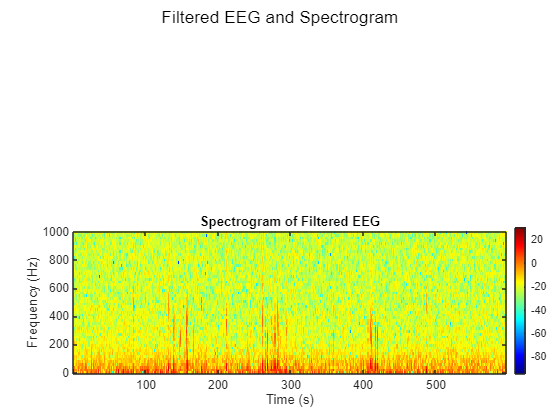

% Compute and plot spectrogram
window = round(0.05*fs);    % 50 ms window
noverlap = round(0.025*fs); % 50% overlap
nfft = 2^nextpow2(window);

[S,F,T_spec] = spectrogram(filtered_signal, window, noverlap, nfft, fs);

% Find indices for frequencies up to 3000 Hz
idx = F <= 1000;

% Convert to dB for plotting
S_dB = 20*log10(abs(S));

% Plot the spectrogram
subplot(2,1,2)
imagesc(T_spec, F(idx), 20*log10(abs(S(idx,:)))); % Use T_spec for time in the spectrogram
axis xy; % Ensure correct orientation
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Filtered EEG');
colormap jet;

% Add a color bar without disrupting alignment
c = colorbar; % Add color bar
c.Position = [0.92, 0.11, 0.02, 0.35]; % Manually position the color bar

% Adjust subplot spacing for better alignment
sgtitle('Filtered EEG and Spectrogram');

## Spike Detection

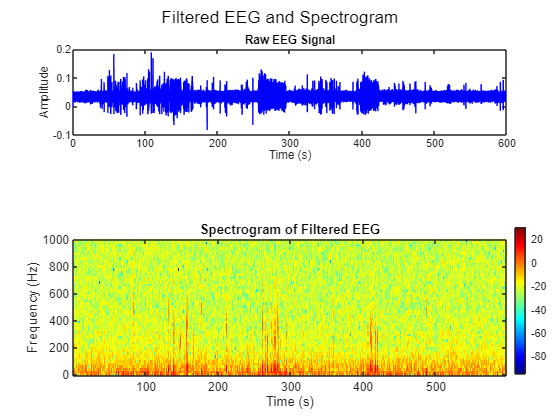

raw_eeg = data(:,1);
fs = fs_rec; % Sampling rate (Hz)
fc = [5 80];  % Cutoff frequency (Hz)
signal_length = size(raw_eeg, 1);

[b_band, a_band] = butter(2, fc/(fs/2), 'bandpass'); % 4th-order Butterworth filter
bandpassed_signal = filtfilt(b_band, a_band, raw_eeg);

fc_notch = [59 61]; % Notch range (60 Hz ± 1 Hz)
[b_notch, a_notch] = butter(2, fc_notch / (fs / 2), 'stop'); % 2nd-order notch filter
filtered_signal = filtfilt(b_notch, a_notch, bandpassed_signal); % Apply notch filter

t_seconds = (0:signal_length-1)/fs;

% Raw EEG signal
subplot(3,1,1);
plot(t_seconds, raw_eeg, 'b');
title('Raw EEG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

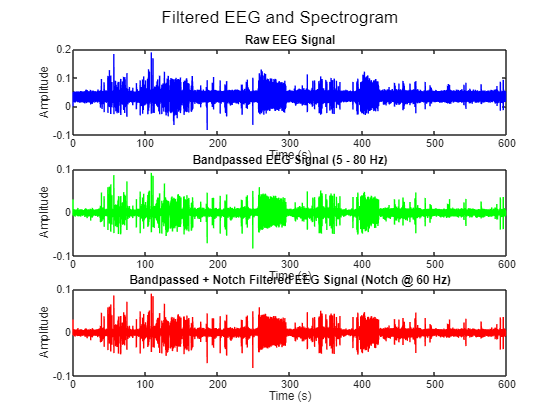


% Bandpassed signal
subplot(3,1,2);
plot(t_seconds, bandpassed_signal, 'g');
title('Bandpassed EEG Signal (5 - 80 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');

% Bandpassed + Notch filtered signal
subplot(3,1,3);
plot(t_seconds, filtered_signal, 'r');
title('Bandpassed + Notch Filtered EEG Signal (Notch @ 60 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');

## Find peaks

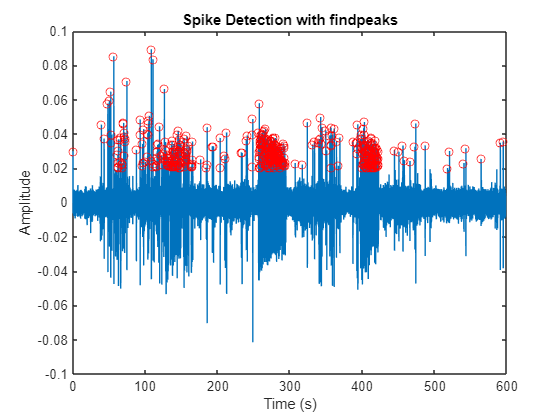

% Find spikes using findpeaks
minpeakh = 0.02; % Min height threshold
minpeakdist = 10;
% peakseek(x,minpeakdist,minpeakh)
[spike_indices, spike_amplitudes] = peakseek(filtered_signal, minpeakdist, minpeakh);

% Plot the signal with detected spikes
figure;
plot(t_seconds, filtered_signal);
hold on;
plot(t_seconds(spike_indices), spike_amplitudes, 'ro'); % Mark spikes
hold off;
title('Spike Detection with findpeaks');
xlabel('Time (s)');
ylabel('Amplitude');

## Average waveforms of found peaks

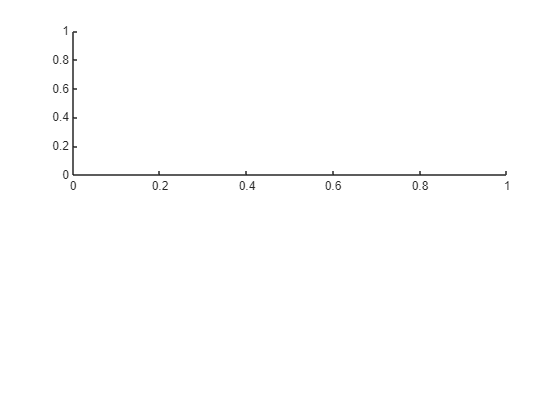

% Step 2: Extract Waveforms Around Each Peak
window_size = round(0.05 * fs); % 50 ms window around each peak
waveforms = [];
for i = 1:length(spike_indices)
    idx = spike_indices(i);
    if idx - window_size > 0 && idx + window_size <= length(filtered_signal)
        waveforms = [waveforms; filtered_signal(idx - window_size : idx + window_size)]; % Collect waveforms
    end
end

% Step 3: Compute the Average Waveform
average_waveform = mean(waveforms, 1);

% Step 4: Plot Waveforms
time_axis = (-window_size:window_size) / fs; % Time axis for waveforms

figure;

% Plot all waveforms
subplot(2, 1, 1);

plot(time_axis, waveforms', 'Color', [0.8 0.8 0.8]); % Plot individual waveforms in gray

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

hold on;
plot(time_axis, average_waveform, 'r', 'LineWidth', 2); % Overlay average waveform in red
title('Detected Spikes and Average Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Individual Waveforms', 'Average Waveform');

% Plot the signal with detected spikes
subplot(2, 1, 2);
plot(t_seconds, signal, 'b'); hold on;
plot(t_seconds(spike_indices), signal(spike_indices), 'ro'); % Mark spikes
title('Signal with Detected Spikes');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Signal', 'Detected Spikes');